# Mécanica Celeste

Alan Amaya 191165

Jonathan Gutierrez 191001

Santiago Pérez Gutiérrez 188475

## Introducción

En nuestro sistema solar, todos los planetas tienen una trayectoria elíptica alrededor del sol y el sol también está no estático y describe un movimiento sobre un origen de referencia

**Las leyes de Kepler.** Las leyes de Kepler son tres leyes empíricas que describen el movimiento de los planetas alrededor del Sol.

- Cada planeta se mueve alrededor del Sol describiendo una elipse con el Sol situado en uno de sus focos.

- Los planetas se mueven con velocidad areolar constante, es decir, el vector de posición que une al sol con un planeta barre áreas iguales en tiempos iguales.

- La razón del cubo del semieje mayor entre el cuadrado del periodo de revolución es la misma para todos los planetas, es decir, existe una constante tal que:

                                                             
$$\frac{R^3 }{T^2 }=C$$


**El principio de conservación del momento angular.** Recordemos que el momento angular de una partícula es igual al momento de su momento lineal, es decir:

                                                          
$$L=r\cdot mr^{\prime } \;$$


Si tomamos derivadas y tenemos en cuetna que el producto vectorial de vectores proporcionales es nulo, resulta entonces que:

                                                            
$$L^{\prime } =r\cdot {{\textrm{mr}}^{\prime } }^{\prime }$$


Por consiguiente, aplicando la seguna ley de Newton obtenemos que la derivada del momento angular es igual al momento de la fuerza.

                                                           
$$L^{\prime } =r\cdot F$$


En este proyecto vamos a derivar las ecuaciones del movimiento planetario basándonos en la suposición que las masas de los planetas se pueden aproximar a masas puntuales. Debido a las grandes distancias que seperan a los cuerpos, no solo en nuestros sistema solar sino que también en todo el universo.

## 1.- Identificación del Problema

El problema consiste en formular un sistema complejo que sirva para modelar el comportamiento de la mecánica celeste con respecto al sol, involucrando una gran cantidad de cuerpos (en este caso 10) y, por tanto, más ecuaciones de las que hasta ahora hemos manejado.

### Requerimientos

### **Funcionales:**

**Simular en una gráfica 3D la mecánica celeste con respecto al sol, haciendo uso de código eficiente y priorizando la memoria.** En este proyecto vamos a derivar las ecuaciones del movimiento planetario basándonos en la suposición que las masas de los planetas se pueden aproximar a masas puntuales. Debido a las grandes distancias que seperan a los cuerpos, no solo en nuestros sistema solar sino que también en todo el universo.

### No funcionales:

Entender la interacción de todos los planetas de nuestro sistema y el sol, para lo que será necesario investigar los datos que tomaremos como iniciales para poder utilizar métodos anteriormente vistos. Estos datos son** las fórmulas que describan, la velocidad tangencial, la velocidad inicial, número de cuerpos que estamos considerando, masa de los cuerpos, distancia entre cada uno de ellos y cordenadas polares en el plano.** 

### Restricciones: 

El tamaño de paso h es un valor que desconocemos actualmente para la resolución de un problema de esta magnitud, además de que anteriormente no hemos ploteado gráficas en 3D y, al manejar números tan imponentes puede que esto signifique un reto para visualizar la información que obtendremos. Debido a esto, tendremos que ir "jugando" con el valor de h hasta encontrarun valor óptimo que nos permita que el programa no se tarde tanto en procesar la información y que no revase el máximo de información matricial que puede manejar Matlab, el cual es de 5 Gb, pero que también nos permita obtener valores certeros y de valor.

## 2.- Modelo Matematico

Para esto tenemos recordar la ley de gravitación de Newton:


$$F^{\prime } =G\frac{m\cdot m^{\prime } }{r^2 }$$


Donde la fueza presenta componentes en x,y,z. Fx, Fy, Fz:


$$\begin{array}{l}
\textrm{Fx}=F\frac{x^{\prime } -x}{r}\\
\textrm{Fy}=F\frac{y^{\prime } -y}{r}\\
\textrm{Fz}=F\frac{z^{\prime } -z}{r}
\end{array}$$


Más adelante, siguinera la segunda ley de dinamicas de Newton obtenemos:


$$\begin{array}{l}
\textrm{Fx}=m\frac{d^2 x}{{\textrm{dt}}^2 }\\
\textrm{Fy}=m\frac{d^2 y}{{\textrm{dt}}^2 }\\
\textrm{Fz}=m\frac{d^2 z}{{\textrm{dt}}^2 }
\end{array}$$


Combinando ambas ecuaciones, obtenemos finalmente:


$$\frac{d^2 x}{{\textrm{dt}}^2 }=G\cdot m^{\prime } \;\frac{x^{\prime } -x}{r^3 }$$



$$\begin{array}{l}
\frac{d^2 y}{{\textrm{dt}}^2 }=G\cdot m^{\prime } \;\frac{y^{\prime } -y}{r^3 }\\
\frac{d^2 z}{{\textrm{dt}}^2 }=G\cdot m^{\prime } \;\frac{z^{\prime } -z}{r^3 }
\end{array}$$


donde r es dado por:


$$r=\sqrt{{\left(x^{\prime } -x\right)}^2 +{\left(y^{\prime } -y\right)}^2 +{\left(z^{\prime } -z\right)}^2 }$$


En este caso $G$es la fuerza gravitacional, $m$y $M\;$son las masas del planeta dado y el Sol respectivamente, $r$es la distancia entre el planera y el Sol y F es la fuerza.

Una vez que contamos con esto, podemos extrapolar a systemma global de ecuaciones que consideran la interacciones de j objetos con masas m1,m2,...,mj en un cuerpo $\alpha$ con masa $m_{\alpha }$

Por lo tanto las ecuaciones de nuestro sistema es:


$$\begin{array}{l}
\frac{d^2 x_{\alpha } }{{\textrm{dt}}^2 }=\sum_{J=1;\;J\not= \alpha \;}^{\textrm{nb}} G\cdot m_j \;\frac{x_j -x_{\alpha } }{{\left(r_{j,\alpha } \right)}^3 }\\
\frac{d^2 y_{\alpha } }{{\textrm{dt}}^2 }=\sum_{J=1;\;J\not= \alpha \;}^{\textrm{nb}} G\cdot m_j \;\frac{y_j -y_{\alpha } }{{\left(r_{j,\alpha } \right)}^3 }\\
\frac{d^2 z_{\alpha } }{{\textrm{dt}}^2 }=\sum_{J=1;\;J\not= \alpha \;}^{\textrm{nb}} G\cdot m_j \;\frac{z_j -z_{\alpha } }{{\left(r_{j,\alpha } \right)}^3 }
\end{array}$$



$$r_{j,\alpha } =\sqrt{{\left(x_j -x_{\alpha } \right)}^2 +{\left(y_j -y_{\alpha } \right)}^2 +{\left(z_j -z_{\alpha } \right)}^2 }$$


donde : 

nb: es el número de cuerpos que consideramos 

G: Constante de gravitación gravitacional

$m_j$: Masa de el cuerpo J

$r_{j,\alpha }$: Distancia entre los cuerpos J y $\alpha$

$x_{\alpha } ,y_{\alpha } ,z_{\alpha }$: Coordenadas Cartesianas del cuerpo $\alpha$

$x_j ,y_j ,z_j$: Coordenadas Cartesianas del cuerpo $j$

## 3.- Implementación

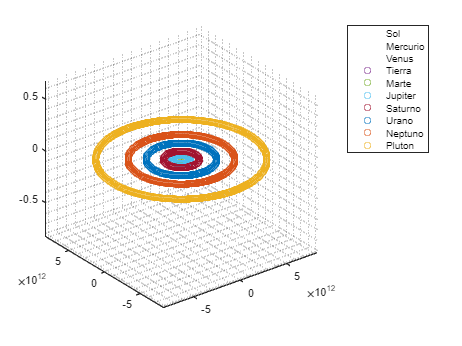

clear all; 
% El Sol es el origen inicialmente
% Los vectores tienen los datos 
% [Sol; Mercurio; Venus; Tierra; Marte; Júpiter;Saturno;Urano
% Neptuno;Pluton]
% Ten-body problem
global G m;
G = 6.67428E-11;              % m3 kg-1 s-2

mS= 1.9891E+30;               % masa del Sol
mM = 3.302E+23;               % masa de Mercurio
mV = 4.869E+24;               % masa de Venus
mT = 5.9736E+24;              % masa de la Tierra
mMar= 6.4185E+23;             % masa de Marte
mJ = 1.899E+27;               % masa de Jupiter
mSat = 5.688E+26;             % masa de Saturno
mU = 8.686E+25;               % masa de Urano
mN = 1.024E+26;               % masa de Neptuno
mP = 1.25E+22;                % masa de Pluton

m = [mS, mM, mV, mT, mMar, mJ, mSat, mU, mN, mP]; 
dM = 69816877462.0779;                 % distancia media Sol/Mercurio (centros) 
dV = 108939114216.059;                 % distancia media Sol/Venus (centros) 
dT = 152098232000;
dMar = 249209300000;
dJ = 816520736459.153;
dS= 1513325782874.55;
dU= 3004419704000;
dN = 4553946490000;
dP = 7304300000000;
d = [dM, dV, dT, dMar, dJ, dS, dU, dN, dP];

r0 = [ [0;0;0]; [dM;0;0]; [dV;0;0]; [dT;0;0]; [dMar;0;0]; [dJ;0;0]; ...
    [dS;0;0]; [dU;0;0]; [dN;0;0]; [dP;0;0] ];    % posiciones iniciales
% movimiento circular uniforme, aceleración centrípeta
% velocidad tangencial de la Luna (eje y), rapidez
vM = sqrt(G * mS/dM);
vV = sqrt(G * mS/dV);
vT = sqrt(G * mS/dT);
vMar = sqrt(G * mS/dMar);
vJ = sqrt(G * mS/dJ);
vS = sqrt(G * mS/dS);
vU = sqrt(G * mS/dU);
vN = sqrt(G * mS/dN);
vP = sqrt(G * mS/dP);
v = [vM, vV, vT, vMar, vJ, vS, vU, vN, vP];
v0 = [ [0;0;0]; [0;vM;0]; [0;vV;0]; [0;vT;0]; [0;vMar;0]; [0;vJ;0]; [0;vS;0]; ...
    [0;vU;0]; [0;vN;0]; [0;vP;0]];     % velocidades iniciales

fhandle = @f;
h = 3000;
nv = 1;

wL = vM/dM;
T = (2*pi)/wL;
y0 = [0;0;0;dM;0;0;0;0;0;0;vM;0];
[y,~] = odeRK4(fhandle,y0,0,nv*T,h);

plot3(y(1,:),y(2,:),y(3,:),'ob');
hold on
plot3(y(4,:),y(5,:),y(6,:),'ok');
colors=['or';'og';'or';'ob';'oc';'om';'oy';'og'];

for i=2:9
    wL = v(i)/d(i);
    T = (2*pi)/wL;
    y0(4:6) = r0(3*i+1:3*(i+1));
    y0([10 11 12]) = v0(3*i+1:3*(i+1));

    [y,~] = classicalRK4(fhandle,y0,0,nv*T,h);
    
    plot3(y(4,:),y(5,:),y(6,:),colors(i-1));
end

legend('Sol','Mercurio','Venus','Tierra','Marte','Jupiter','Saturno','Urano','Neptuno','Pluton');
hold off;

grid minor;

## 4.- Pruebas y resultados

Algunas de las primeras pruebas que podemos realizar con esta simulación, es modficar el valor de $h$, esta variable representa el calculo de posiciones que se van a realizar en cada minuto. El cambiar esto hace que la simulación sea más precisa, sin embargo, notamos que al incrementar a un núemero bastante grande, salia un error. Este error mostraba que el tamaño del vector sobrepasaba la capacidad de memoria de 5GB de Matlab.

Finalmente, tras unas cuantas pruebas determinamos que un buen tamaño de h ronda alrededor de los 3000, de manera que obtenemos esta gráfica:

                                                                                                                    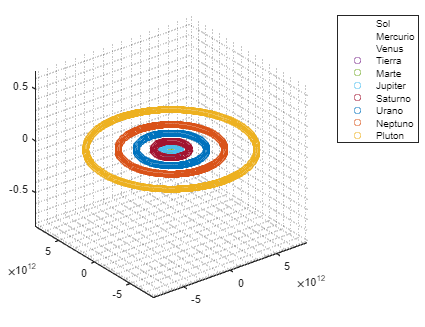

                                                                                                                                              Figura 1. Sistema solar 

Si bien a primera vista sólo se aprecia la orbita de 5 o 6 planetas, Matlab nos permite hacer un acercamiento, de manera que nos sea posible cersiorarnos de la correcta simulación del sistema. Con dicho acercamiento obtenemos una imágen cómo esta:

                                                                                                                    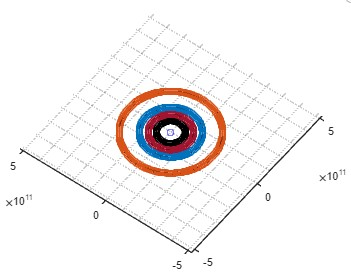

                                                                                                                           Figura 2. Acercamiento del sistema solar modelado

Cómo se puede notar en la Figura 2, ahora podemos apreciar las 5 primeras orbitas con claridad, con el Sol al centro. Es decir, notamos el circulo del Sol, pues lo consideramos como una materia estática, después encontramos la orbita de Mercurio, Venus, la Tierra y Marte. De esta manera, no queda duda de que la simulación se realizó con éxito.

Por otro lado, también podemos modificar el número de vueltas que quermos simular, esto lo que hace es que muestr una mayor cantidad de vueltas. Lo que llegamos a observar es que cuando los valores de las vueltas estan entre 2-6 se llegan a observar unas pequeñas diferencias entre las orbitas. Cuando este número es mayor, las líneas que observamos pierden claridez, asi como el tiempo de espera para que se ejecute el programa incrementa. Consideramos que manteniendo el número de vueltas a 4, se observan los mejores resultados.

## Conclusión

La simulación de sistemas complejos puede realizarce mediante fórmulas y derivadas que hemos visto en clase, cómo por ejemplo con el método odeRK4, pero resolver problemas de esta manera tiene muchos supuestos, lo que le quita exactitud a la solución. Por ejemplo, se da por supuesto la posición inicial de cada planeta que, cómo sabemos están en constante movimiento y, en especial para la resolución de este problema, también se estima uno de los cuerpos inmóvil con respecto al resto, lo cual sabemos que es mentira, pues el sol también tiene movimientos de traslación.

Así mismo, consideramos interesante la necesidad de contemplar la interacción de cada planeta, pero este modelo cambiaría y se compllicaría significativamente si, a su vez, también consideraramos las fuerzas que ejerce cada planeta sobre cada otro planeta, es decir, tendríamos una relación de fuerzas de 9 factorial, que expresado en numeros exactos es igual a 362,880, con lo que obtendríamos cada vez ecuaciones y datos diferentes que harían dinámico el modelo. 

En consecuencia y finalmente, consideramos que el poder de la simulación y el modelado es inmenso, tan inmenso que es capaz modelar lo más grande de lo que el ser humano tiene noción, nuestro sistema solar. Además y, al igual que en proyectos anteriores, el tamaño de paso **h **sigue siendo de suma relevancia en la resolución de sistemas, simples o complejos, de manera que nuca se deja de lado la importancia de los errores de redondeo que se pueden ocasionar mediante el tamaño de esta variable, entre otras cosas. 

#### Código:

function ydot = f(~,y)
    global G m;
    r = y(1:6); % vectores de posición rT y rS
    v = y(7:12);
    dr = r(4:6) - r(1:3); % Sol a cualquier planeta
    u = dr / norm(dr);
    dr2 = norm(dr)^2;
    F = (G*m(1)*m(2)/dr2) * u;
    a = [F/m(1); -F/m(2)]; % par acción - reacción; tercera ley de Newton
    ydot = [v;a];
end

Método RK4

function [y,t] = classicalRK4(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    y = zeros(length(y0),n);
    y(:,1) = y0;
  
    
    for i = 1:1:n-1
    k1 = f(t(i),y(:,i));
    k2 = f(t(i)+0.5*h, y(:,i)+0.5*k1*h);
    k3 = f(t(i)+0.5*h, y(:,i)+0.5*k2*h);    
    k4 = f(t(i)+h, y(:,i)+k3*h); 
    phi = (1/6)*(k1 +2*k2 +2*k3+k4);
    y(:,i+1) = y(:,i) + phi*h;

    end

end